## Import Data

clear all;
clc;
data = readtable("step_multiple_15V_75ohm.csv");
data = fillmissing(data,'nearest')

data = 1282×3 table
      Var1         Var2       Var3  
    _________    ________    _______

          -20           1          2
          -20           1          2
          -20     14.8984    0.03871
    -19.98438     14.8984    0.03871
    -19.96875    14.89883    0.05127
    -19.95313    14.89925    0.05127
     -19.9375    14.89968    0.03871
    -19.92188    14.90011    0.03871
    -19.90625    14.90011    0.03871
    -19.89063    14.90053    0.05127
      -19.875    14.90011    0.05127
    -19.85938    14.90011    0.03871
    -19.84375    14.89925    0.03871
    -19.82813    14.89797    0.03871
     -19.8125    14.89712    0.03871
    -19.79688    14.89669    0.03871


data([1,2],:) = []

data = 1280×3 table
      Var1         Var2       Var3  
    _________    ________    _______

          -20     14.8984    0.03871
    -19.98438     14.8984    0.03871
    -19.96875    14.89883    0.05127
    -19.95313    14.89925    0.05127
     -19.9375    14.89968    0.03871
    -19.92188    14.90011    0.03871
    -19.90625    14.90011    0.03871
    -19.89063    14.90053    0.05127
      -19.875    14.90011    0.05127
    -19.85938    14.90011    0.03871
    -19.84375    14.89925    0.03871
    -19.82813    14.89797    0.03871
     -19.8125    14.89712    0.03871
    -19.79688    14.89669    0.03871
    -19.78125    14.89626    0.05127
    -19.76563    14.89584    0.05127


data_test = readtable("step_multiple_60to70_75ohm.csv");
data_test = fillmissing(data_test,'nearest');
data_test([1,2],:) = [];
% Step info
step_bot=75;
step_top=80;

## Assign Variables

% Seperate values
t = table2array(data(:,1))+5

t =  -15.000000000000000
 -14.984380000000002
 -14.968750000000000
 -14.953130000000002
 -14.937500000000000
 -14.921880000000002
 -14.906250000000000
 -14.890630000000002
 -14.875000000000000
 -14.859380000000002


ADC = round(table2array(data(:,2))/30*1024)

ADC =    509
   509
   509
   509
   509
   509
   509
   509
   509
   509


OCR = table2array(data(:,3))

OCR =    0.038710000000000
   0.038710000000000
   0.051270000000000
   0.051270000000000
   0.038710000000000
   0.038710000000000
   0.038710000000000
   0.051270000000000
   0.051270000000000
   0.038710000000000


% Match to duty cycle
OCR = round(OCR/5)*(step_top-step_bot)+step_bot;

% Find index before step
idx = find(OCR>75,1,'first')

idx =     24



% Trim data with new index
t = t(idx-5:end);
ADC = ADC(idx-5:end);
OCR = OCR(idx-5:end);

% Reset time and find sampling time
t = t-t(1);
T_s=t(2)-t(1)

T_s =    0.015619999999998


## Plot Real Data

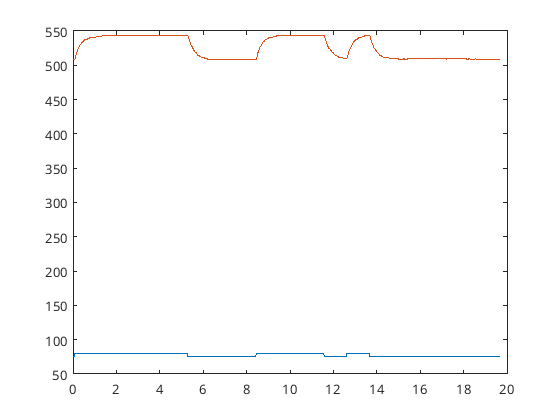

clf;
plot(t,OCR)
hold on
plot(t,ADC)
hold off

clf

## Identify Transfer Functions

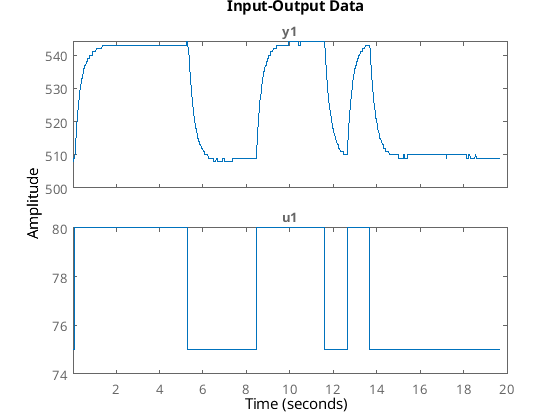

idd = iddata(ADC,OCR,T_s);
plot(idd)

G=tfest(idd,2,0)

G =
 
  From input "u1" to output "y1":
          4122
  ---------------------
  s^2 + 163.7 s + 606.9
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using TFEST on time domain data "idd".
Fit to estimation data: 96.05%                  
FPE: 0.3826, MSE: 0.3795                        


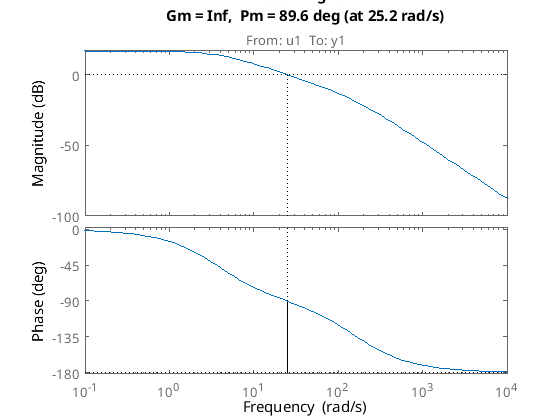

margin(G)

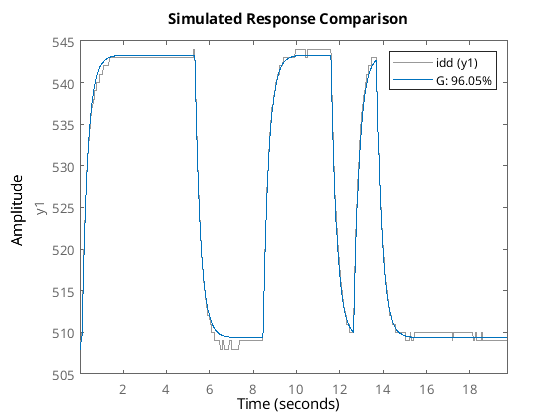

compare(idd,G)  % Passer meget godt med dataet

## Create PID Controller

abs(pole(G))

ans = 1.0e+02 *

   1.599132933691860
   0.037953676139054


gm = 60; Ni=0.5; alpha=1;
[wc, Kp, taui,taud, ok] = findpid(G, gm, Ni,alpha)

ans = 'Found 1 valid solution(s) out of 1 phase crossing(s)'

wc =    5.368951062294940


Kp =    0.114139864134527


taui =    0.093128060620891


taud =    0.186256121241782


ok =      1


s=tf('s');
Cpid=Kp*(taui*s+1)/(taui*s)*(taud*s+1)/(alpha*taud*s+1)

Cpid =
 
  0.00198 s^2 + 0.03189 s + 0.1141
  --------------------------------
      0.01735 s^2 + 0.09313 s
 
Continuous-time transfer function.



Cpid = minreal(Cpid)

Cpid =
 
  0.1141 s + 1.226
  ----------------
         s
 
Continuous-time transfer function.



Gol=minreal(G*Cpid)

Gol =
 
  From input to output "y1":
       470.5 s + 5052
  -------------------------
  s^3 + 163.7 s^2 + 606.9 s
 
Continuous-time transfer function.



Gcl=minreal(Gol/(1+Gol))

Gcl =
 
  From input "y1" to output "y1":
          470.5 s + 5052
  -------------------------------
  s^3 + 163.7 s^2 + 1077 s + 5052
 
Continuous-time transfer function.



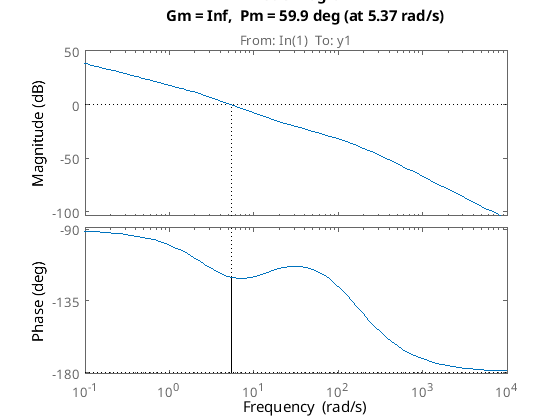

margin(Gol);

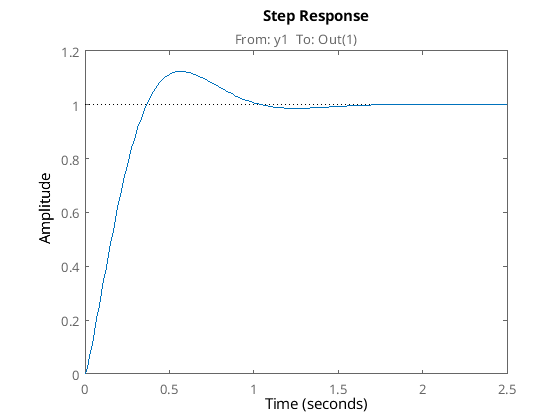

step(1*Gcl);

## Z-Transform

format long
Gz=c2d(Cpid,1/10e3,'tustin');
Gz.Variable= 'z^-1'

Gz =
 
  0.1142 - 0.1141 z^-1
  --------------------
        1 - z^-1
 
Sample time: 0.0001 seconds
Discrete-time transfer function.




[num, den] = tfdata(Gz, 'v')

num =    0.114201145269007  -0.114078583000048


den =      1    -1


%open_system('pidTF2Code.slx')
%stepz([num],[den]);

e =[0,0,0];
u = [78,78,78];

u1=num(1)*e(1)+num(2)*e(2)+num(3)*e(3)-den(2)*u(2)-den(3)*u(3)

u1 = 78.0000

## Discrete Implementation

% Build time vector
dt=1/10e3;
t = 0:dt:14;

% Build step input
u = ones(size(t));
u(1:5)=0;

% Initialize values
y = zeros(size(t));

% Step through time and solve the difference equation
for i = 5:length(t)
        uvals = num(1)*u(i)+num(2)*u(i-1)+num(3)*u(i-2)+num(4)*u(i-3)+num(5)*u(i-4);
        yvals = -den(2)*y(i-1)-den(3)*y(i-2)-den(4)*y(i-3)-den(5)*y(i-4);
        y(i) = uvals + yvals;
end

Index exceeds the number of array elements. Index must not exceed 3.


scatter(t,y,3)